# OGLO notebook 5

HNXJ@github

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

addpath('fieldtrip');ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


## Autoencoders

- Spike to task behavior

numLatentChannels = 5;
imageSize = [41 1000 1];

layersE = [
    imageInputLayer(imageSize,Normalization="rescale-zero-one")
    convolution2dLayer(10,20,Padding="same",Stride=2)
    reluLayer
    convolution2dLayer(20,20,Padding="same",Stride=10)
    reluLayer
    fullyConnectedLayer(10)
    sigmoidLayer
    fullyConnectedLayer(2)
    softmaxLayer
    ];

netE = dlnetwork(layersE);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss
    _________    _____    ___________    _________    ____________
            1        1       00:00:00        0.001         0.45994
           50        2       00:00:01        0.001         0.46275
          100        4       00:00:02        0.001          0.3838
          150        5       00:00:03        0.001         0.27262
          200        7       00:00:04        0.001         0.17269
          250        9       00:00:05        0.001         0.10427
          300       10       00:00:06        0.001        0.093807
          350       12       00:00:07        0.001        0.067696
          400       14       00:00:08        0.001        0.049107
          450       15       00:00:08        0.001        0.064015
          500       17       00:00:09        0.001        0.026833
          550       19       00:00:10        0.001        0.029285
          600       20       00:00:11        0.001        0.02

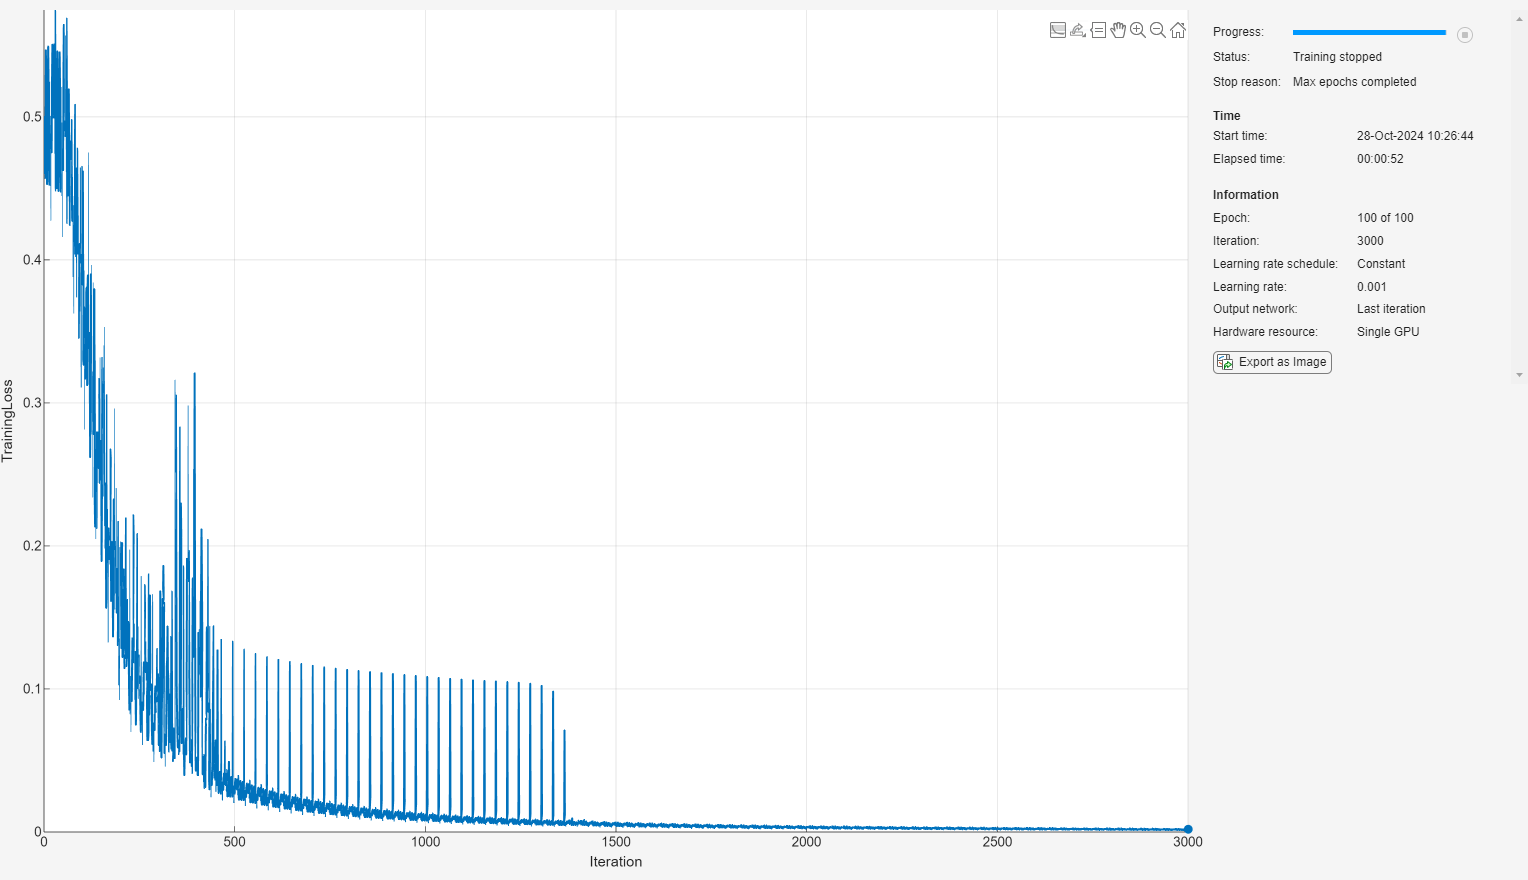

options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...        % Number of epochs to train for
    'MiniBatchSize', 10, ...    % Mini-batch size
    'InitialLearnRate', 1e-3, ...
    'Verbose', true, ...
    'Plots', 'training-progress');


% xG = z{9}{1}{1};
xG = z{7}{1}{2};
xG = xG(:, :, :, 1);
xG = permute(xG, [2, 3, 4, 1]);

XTrain = cat(4, xG(:, 3031:4030, 1, 1:150), xG(:, 2001:3000, 1, 1:150)); % [Neuron/Channel - Time/Freq - 1] x Trial
YTrain = zeros(300, 2); % [A - B - X - Fx - 1] x Trial
YTrain(1:150, 1) = 1;
YTrain(151:300, 2) = 1;

XTest = cat(4, xG(:, 3031:4030, 1, 151:200), xG(:, 2001:3000, 1, 151:200)); % [Neuron/Channel - Time/Freq - 1] x Trial
YTest = zeros(50, 2); % [A - B - X - Fx - 1] x Trial
YTest(1:50, 1) = 1;
YTest(51:100, 2) = 1;

% Train the neural network
netE = trainnet(XTrain, YTrain, netE, "l1loss", options);

% Test the network (replace testData with actual test set if available)
testData = XTest(:, :, :, 1:100); % 10 random test samples
predictedLabels = predict(netE, testData);
predictedLabels = round(predictedLabels);
aN = ceil(size(predictedLabels, 1)/2);
aa = sum(predictedLabels(1:aN, 1));
ab = sum(predictedLabels(aN+1:end, 2));
disp((aa + ab)/(2*aN));

    0.5900




% plot(YTest(1, 1, :));

trailingAvgE = [];
trailingAvgSqE = [];
trailingAvgD = [];
trailingAvgSqD = [];

numObservationsTrain = size(XTrain, 4);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info="Epoch", ...
    XLabel="Iteration");

epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop
        iteration = iteration + 1;

        % Read mini-batch of data.
        X = next(mbq);

        % Evaluate loss and gradients.
        [loss,gradientsE,gradientsD] = dlfeval(@modelLoss,netE,netD,X);

        % Update learnable parameters.
        [netE,trailingAvgE,trailingAvgSqE] = adamupdate(netE, ...
            gradientsE,trailingAvgE,trailingAvgSqE,iteration,learnRate);

        [netD, trailingAvgD, trailingAvgSqD] = adamupdate(netD, ...
            gradientsD,trailingAvgD,trailingAvgSqD,iteration,learnRate);

        % Update the training progress monitor. 
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        monitor.Progress = 100*iteration/numIterations;
    end
end

dsTest = arrayDatastore(XTest,IterationDimension=4);
numOutputs = 1;

mbqTest = minibatchqueue(dsTest,numOutputs, ...
    MiniBatchSize = miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");

YTest = modelPredictions(netE,netD,mbqTest);

err = mean((XTest-YTest).^2,[1 2 3]);
figure
histogram(err)
xlabel("Error")
ylabel("Frequency")
title("Test Data")

## Appendix

nPath = "neuronData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

cFlag = 0;% +10 for SPK, otherwise +0 for convolved
z = cell(1, 10);

for i = 1:10 

    nFile = nFiles{i+cFlag};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

1. loaded : 01_Neurons_OGLO_V1.mat
2. loaded : 02_Neurons_OGLO_V2.mat
3. loaded : 03_Neurons_OGLO_V3d.mat
4. loaded : 04_Neurons_OGLO_V3a.mat
5. loaded : 05_Neurons_OGLO_V4.mat
6. loaded : 06_Neurons_OGLO_TEO.mat
7. loaded : 07_Neurons_OGLO_MT.mat
8. loaded : 08_Neurons_OGLO_MST.mat
9. loaded : 09_Neurons_OGLO_FEF.mat
10. loaded : 10_Neurons_OGLO_PFC.mat


nPath = "lfpData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 10);

for i = 7:10

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

7. loaded : 07_LFPs_OGLO_MST.mat
8. loaded : 08_LFPs_OGLO_TEO.mat
9. loaded : 09_LFPs_OGLO_FEF.mat
10. loaded : 10_LFPs_OGLO_PFC.mat


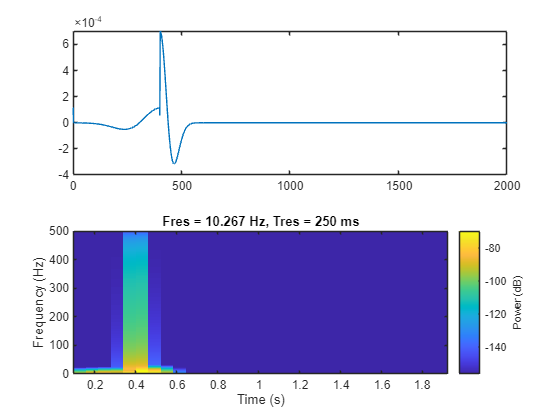

t = [linspace(-3, 0, 400), i*linspace(0, 3, 1600)];
y = exp(-t.^2);
y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram");

## END